T1_sheet8=readtable('8per.xlsx','Sheet','T1');

VoltT18=T1_sheet8.Volt_peak(1:30,:);
timeT18=T1_sheet8.tau(1:30,:)*1e-3;
% 
% T18per_fit(timeT18, VoltT18)
% title('8 % T1 fit')

delta_y=VoltT18.*0+1/12^0.5;
delta_x=timeT18.*0+0.0001/12^0.5;
x=timeT18;
y=VoltT18;

T18 = table(x,delta_x,y,delta_y);
writetable(T18,'T1_8.xlsx') ;

T1_sheet4=readtable('4per.xlsx','Sheet','T1');

VoltT14=T1_sheet4.Volt_peak(1:25,:);
timeT14=T1_sheet4.tau(1:25,:)*1e-3;

% T1_4_2_1_05per_fit(timeT14, VoltT14)
% title('4 % T1 fit')


delta_y=VoltT14.*0+1/12^0.5;
delta_x=timeT14.*0+0.0001/12^0.5;
x=timeT14;
y=VoltT14;

T14 = table(x,delta_x,y,delta_y);
writetable(T14,'T1_4.xlsx') ;

T1_sheet2=readtable('2per.xlsx','Sheet','T1');

VoltT12=T1_sheet2.Volt_peak(1:24,:);

timeT12=T1_sheet2.tau(1:24,:)*1e-3;

% T1_4_2_1_05per_fit(timeT12, VoltT12)
% title('2 % T1 fit')

delta_y=VoltT12.*0+1/12^0.5;
delta_x=timeT12.*0+0.0001/12^0.5;
x=timeT12;
y=VoltT12;

T12 = table(x,delta_x,y,delta_y);
writetable(T12,'T1_2.xlsx') ;

T1_sheet1=readtable('1per.xlsx','Sheet','T1');

VoltT11=T1_sheet1.Volt_peak(1:26,:);
VoltT11(8,:)=[];
timeT11=T1_sheet1.tau(1:26,:)*1e-3;
timeT11(8,:)=[];

% T1_4_2_1_05per_fit(timeT11, VoltT11)
% title('1 % T1 fit')

delta_y=VoltT11.*0+1/12^0.5;
delta_x=timeT11.*0+0.0001/12^0.5;
x=timeT11;
y=VoltT11;

T11 = table(x,delta_x,y,delta_y);
writetable(T11,'T1_1.xlsx') ;

T1_sheet05=readtable('0.5per.xlsx','Sheet','T1');
VoltT105=T1_sheet05.Var107(1:23,:);
timeT105=T1_sheet05.Var108(1:23,:)*1e-3;

% T1_4_2_1_05per_fit(timeT105, VoltT105)
% title('0.5 % T1 fit')

delta_y=VoltT105.*0+1/12^0.5;
delta_x=timeT105.*0+0.0001/12^0.5;
x=timeT105;
y=VoltT105;

T105 = table(x,delta_x,y,delta_y);
writetable(T105,'T1_05.xlsx') ;

T1_sheet025=readtable('0.25per.xlsx','Sheet','T1');

VoltT1025=T1_sheet025.Volt_peak(1:23,:);
timeT1025=T1_sheet025.tau(1:23,:)*1e-3;

% T1_4_2_1_05per_fit(timeT105, VoltT105)
% title('0.5 % T1 fit')

delta_y=VoltT1025.*0+1/12^0.5;
delta_x=timeT1025.*0+0.0001/12^0.5;
x=timeT1025;
y=VoltT1025;

T1025 = table(x,delta_x,y,delta_y);
writetable(T1025,'T1_025.xlsx') ;

T1_sheet0125=readtable('0.125per.xlsx','Sheet','T1');

VoltT10125=T1_sheet0125.Volt_peak(1:23,:);
timeT10125=T1_sheet0125.tau(1:23,:)*1e-3;

% T1_4_2_1_05per_fit(timeT105, VoltT105)
% title('0.5 % T1 fit')

delta_y=VoltT10125.*0+1/12^0.5;
delta_x=timeT10125.*0+0.0001/12^0.5;
x=timeT10125;
y=VoltT10125;

T10125 = table(x,delta_x,y,delta_y);
writetable(T10125,'T1_0125.xlsx') ;

T1_sheetu=readtable('unknown.xlsx','Sheet','T1');

VoltT1u=T1_sheetu.Volt_peak(1:23,:);
timeT1u=T1_sheetu.tau(1:23,:)*1e-3;

% T1_4_2_1_05per_fit(timeT105, VoltT105)
% title('0.5 % T1 fit')

delta_y=VoltT1u.*0+1/12^0.5;
delta_x=timeT1u.*0+0.0001/12^0.5;
x=timeT1u;
y=VoltT1u;

T1u = table(x,delta_x,y,delta_y);
writetable(T1u,'T1_u.xlsx') ;

T1_sheetg=readtable('gly.xlsx','Sheet','T1');
VoltT1g=T1_sheetg.Var88(1:20,:);
VoltT1g(6:7,:)=[];
timeT1g=T1_sheetg.Var89(1:20,:)*1e-3;
timeT1g(6:7,:)=[];

% 
% T1_4_2_1_05per_fit(timeT1g, VoltT1g)
% title('gly T1 fit')

delta_y=VoltT1g.*0+1/12^0.5;
delta_x=timeT1g.*0+0.0001/12^0.5;
x=timeT1g;
y=VoltT1g;

T1g = table(x,delta_x,y,delta_y);
writetable(T1g,'T1_g.xlsx') ;

Plot results

figure;
T1_res = [1/0.2529,1/0.5035,1/1.033,1/2.033,1/4.388]

T1_res =     3.9541    1.9861    0.9681    0.4919    0.2279


xticks([0.5,1,2,4,8])
per=[0.5,1,2,4,8]

per =     0.5000    1.0000    2.0000    4.0000    8.0000


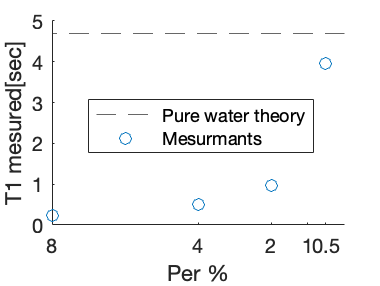

yline(4.70,'--')
hold on
scatter(per,T1_res)
set(gca, 'XDir','reverse')
xlabel('Per %')
ylabel('T1 mesured[sec]')
legend(["Pure water theory","Mesurmants"])
legend("Position",[0.44551,0.52522,0.16429,0.063095])

% T1_per_fit(per, T1_res)

figure;

FitT1(timeT18, VoltT18)

ans =      General model:
     ans(x) = a*(1-2*exp(-b*(x-c)))
     Coefficients (with 95% confidence bounds):
       a =       9.264  (9.153, 9.375)
       b =       4.388  (4.311, 4.465)
       c =    0.004171  (0.002214, 0.006128)

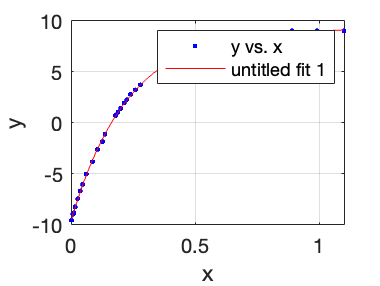

hold on

FitT1(timeT14,VoltT14)

ans =      General model:
     ans(x) = a*(1-2*exp(-b*(x-c)))
     Coefficients (with 95% confidence bounds):
       a =       7.519  (7.382, 7.656)
       b =       2.033  (1.975, 2.091)
       c =     0.01031  (0.002393, 0.01823)

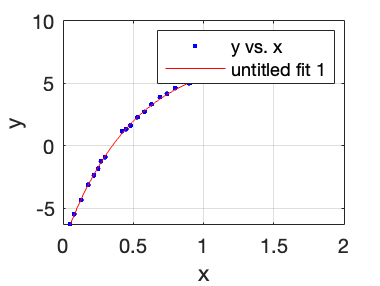

hold on

FitT1(timeT12,VoltT12)

ans =      General model:
     ans(x) = a*(1-2*exp(-b*(x-c)))
     Coefficients (with 95% confidence bounds):
       a =       5.859  (5.59, 6.129)
       b =       1.033  (0.9732, 1.092)
       c =    0.006164  (-0.0241, 0.03643)

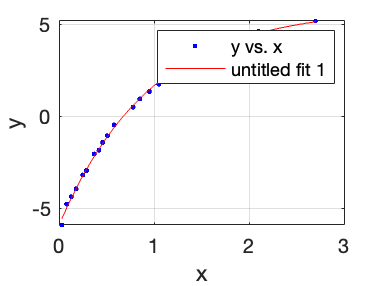

hold on

FitT1(timeT11,VoltT11)

ans =      General model:
     ans(x) = a*(1-2*exp(-b*(x-c)))
     Coefficients (with 95% confidence bounds):
       a =       6.112  (5.969, 6.254)
       b =      0.5035  (0.4862, 0.5209)
       c =    -0.02982  (-0.06595, 0.006312)

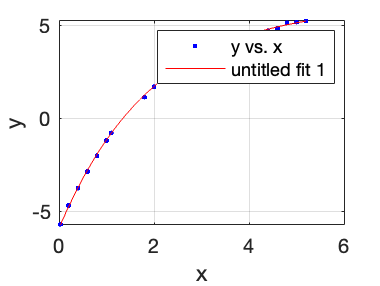

hold on

FitT1(timeT105,VoltT105)

ans =      General model:
     ans(x) = a*(1-2*exp(-b*(x-c)))
     Coefficients (with 95% confidence bounds):
       a =       6.114  (6.04, 6.188)
       b =      0.2529  (0.248, 0.2579)
       c =    -0.04782  (-0.08903, -0.006617)

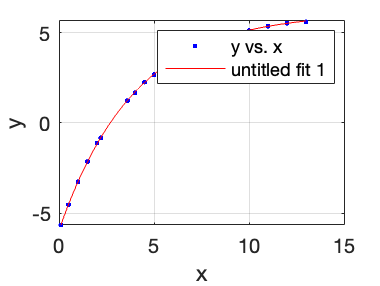

hold on

FitT1(timeT1025,VoltT1025)

ans =      General model:
     ans(x) = a*(1-2*exp(-b*(x-c)))
     Coefficients (with 95% confidence bounds):
       a =       7.773  (7.035, 8.511)
       b =     0.09114  (0.07701, 0.1053)
       c =     0.09128  (-0.634, 0.8166)

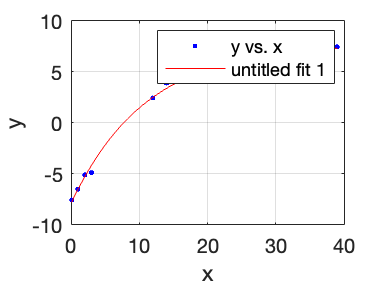

hold on

FitT1(timeT10125,VoltT10125)

ans =      General model:
     ans(x) = a*(1-2*exp(-b*(x-c)))
     Coefficients (with 95% confidence bounds):
       a =       8.071  (6.154, 9.988)
       b =     0.03233  (0.01897, 0.04569)
       c =      -0.709  (-7.664, 6.246)

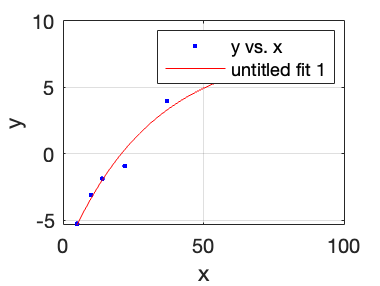

hold on

FitT1(timeT1u,VoltT1u)

ans =      General model:
     ans(x) = a*(1-2*exp(-b*(x-c)))
     Coefficients (with 95% confidence bounds):
       a =       5.013  (3.474, 6.553)
       b =      0.2313  (0.1509, 0.3118)
       c =      0.7301  (0.07019, 1.39)

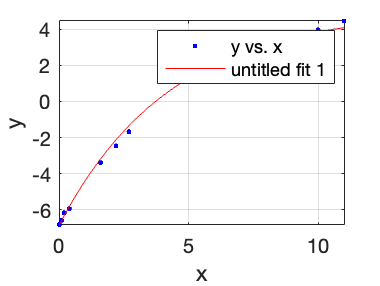

hold on

FitT1(timeT1g,VoltT1g)

ans =      General model:
     ans(x) = a*(1-2*exp(-b*(x-c)))
     Coefficients (with 95% confidence bounds):
       a =       7.267  (6.698, 7.836)
       b =       0.212  (0.1871, 0.2368)
       c =     -0.2916  (-0.6066, 0.02334)

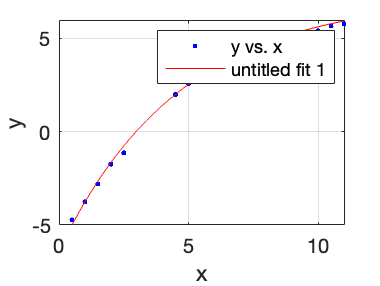

hold on


f=figure;
a=9.264;
b=4.388;
c=0.004171;

scatter(timeT18, VoltT18)
hold on
tm8 = linspace(0,max(timeT18),10000)

tm8 =          0    0.0001    0.0002    0.0003    0.0004    0.0006    0.0007    0.0008    0.0009    0.0010    0.0011    0.0012    0.0013    0.0014    0.0015    0.0017    0.0018    0.0019    0.0020    0.0021    0.0022    0.0023    0.0024    0.0025    0.0026    0.0028    0.0029    0.0030    0.0031    0.0032    0.0033    0.0034    0.0035    0.0036    0.0037    0.0039    0.0040    0.0041    0.0042    0.0043    0.0044    0.0045    0.0046    0.0047    0.0048    0.0050    0.0051    0.0052    0.0053    0.0054


fun8 = a*(1-2*exp(-b.*(tm8-c)))

fun8 =    -9.6062   -9.5971   -9.5880   -9.5789   -9.5698   -9.5607   -9.5517   -9.5426   -9.5335   -9.5244   -9.5154   -9.5063   -9.4972   -9.4882   -9.4791   -9.4701   -9.4610   -9.4520   -9.4430   -9.4339   -9.4249   -9.4159   -9.4069   -9.3979   -9.3889   -9.3799   -9.3709   -9.3619   -9.3529   -9.3439   -9.3349   -9.3259   -9.3170   -9.3080   -9.2990   -9.2901   -9.2811   -9.2722   -9.2632   -9.2543   -9.2454   -9.2364   -9.2275   -9.2186   -9.2097   -9.2007   -9.1918   -9.1829   -9.1740   -9.1651


plot(tm8,fun8)
hold on


a=7.519;
b=2.033;
c=0.01031;

scatter(timeT14,VoltT14)
hold on
tm4 = linspace(0,max(timeT14),10000)

tm4 =          0    0.0002    0.0003    0.0005    0.0007    0.0009    0.0010    0.0012    0.0014    0.0015    0.0017    0.0019    0.0020    0.0022    0.0024    0.0026    0.0027    0.0029    0.0031    0.0032    0.0034    0.0036    0.0037    0.0039    0.0041    0.0043    0.0044    0.0046    0.0048    0.0049    0.0051    0.0053    0.0054    0.0056    0.0058    0.0060    0.0061    0.0063    0.0065    0.0066    0.0068    0.0070    0.0071    0.0073    0.0075    0.0077    0.0078    0.0080    0.0082    0.0083


fun4 = a*(1-2*exp(-b.*(tm4-c)))

fun4 =    -7.8375   -7.8322   -7.8269   -7.8216   -7.8163   -7.8110   -7.8057   -7.8004   -7.7951   -7.7898   -7.7845   -7.7793   -7.7740   -7.7687   -7.7634   -7.7581   -7.7528   -7.7476   -7.7423   -7.7370   -7.7317   -7.7265   -7.7212   -7.7159   -7.7107   -7.7054   -7.7001   -7.6949   -7.6896   -7.6844   -7.6791   -7.6739   -7.6686   -7.6634   -7.6581   -7.6529   -7.6476   -7.6424   -7.6371   -7.6319   -7.6267   -7.6214   -7.6162   -7.6110   -7.6057   -7.6005   -7.5953   -7.5901   -7.5848   -7.5796


plot(tm4,fun4)
hold on



a=5.859;
b=1.033;
c=0.006164;



scatter(timeT12,VoltT12)
hold on
tm2 = linspace(0,max(timeT12),10000)

tm2 =          0    0.0003    0.0005    0.0008    0.0011    0.0014    0.0016    0.0019    0.0022    0.0024    0.0027    0.0030    0.0032    0.0035    0.0038    0.0041    0.0043    0.0046    0.0049    0.0051    0.0054    0.0057    0.0059    0.0062    0.0065    0.0068    0.0070    0.0073    0.0076    0.0078    0.0081    0.0084    0.0086    0.0089    0.0092    0.0095    0.0097    0.0100    0.0103    0.0105    0.0108    0.0111    0.0113    0.0116    0.0119    0.0122    0.0124    0.0127    0.0130    0.0132


fun2 = a*(1-2*exp(-b.*(tm2-c)))

fun2 =    -5.9339   -5.9306   -5.9273   -5.9240   -5.9207   -5.9174   -5.9141   -5.9108   -5.9076   -5.9043   -5.9010   -5.8977   -5.8944   -5.8912   -5.8879   -5.8846   -5.8813   -5.8781   -5.8748   -5.8715   -5.8682   -5.8650   -5.8617   -5.8584   -5.8552   -5.8519   -5.8486   -5.8454   -5.8421   -5.8388   -5.8356   -5.8323   -5.8291   -5.8258   -5.8225   -5.8193   -5.8160   -5.8128   -5.8095   -5.8063   -5.8030   -5.7998   -5.7965   -5.7932   -5.7900   -5.7868   -5.7835   -5.7803   -5.7770   -5.7738


plot(tm2,fun2)
hold on



a=6.112;
b=0.5035;
c=-0.02982;

tm1 = linspace(0,max(timeT11),10000)

tm1 =          0    0.0005    0.0010    0.0016    0.0021    0.0026    0.0031    0.0036    0.0042    0.0047    0.0052    0.0057    0.0062    0.0068    0.0073    0.0078    0.0083    0.0088    0.0094    0.0099    0.0104    0.0109    0.0114    0.0120    0.0125    0.0130    0.0135    0.0140    0.0146    0.0151    0.0156    0.0161    0.0166    0.0172    0.0177    0.0182    0.0187    0.0192    0.0198    0.0203    0.0208    0.0213    0.0218    0.0224    0.0229    0.0234    0.0239    0.0244    0.0250    0.0255


fun1 = a*(1-2*exp(-b.*(tm1-c)))

fun1 =    -5.9298   -5.9267   -5.9235   -5.9204   -5.9172   -5.9141   -5.9109   -5.9078   -5.9046   -5.9015   -5.8983   -5.8952   -5.8921   -5.8889   -5.8858   -5.8826   -5.8795   -5.8764   -5.8732   -5.8701   -5.8669   -5.8638   -5.8607   -5.8575   -5.8544   -5.8513   -5.8481   -5.8450   -5.8419   -5.8387   -5.8356   -5.8325   -5.8294   -5.8262   -5.8231   -5.8200   -5.8169   -5.8137   -5.8106   -5.8075   -5.8044   -5.8012   -5.7981   -5.7950   -5.7919   -5.7888   -5.7857   -5.7825   -5.7794   -5.7763


plot(tm1,fun1)
hold on
scatter(timeT11,VoltT11)
hold on


a=6.114;
b=0.2529;
c=-0.04782;

tm05 = linspace(0,max(timeT105),10000)

tm05 =          0    0.0013    0.0026    0.0039    0.0052    0.0065    0.0078    0.0091    0.0104    0.0117    0.0130    0.0143    0.0156    0.0169    0.0182    0.0195    0.0208    0.0221    0.0234    0.0247    0.0260    0.0273    0.0286    0.0299    0.0312    0.0325    0.0338    0.0351    0.0364    0.0377    0.0390    0.0403    0.0416    0.0429    0.0442    0.0455    0.0468    0.0481    0.0494    0.0507    0.0520    0.0533    0.0546    0.0559    0.0572    0.0585    0.0598    0.0611    0.0624    0.0637


fun05 = a*(1-2*exp(-b.*(tm05-c)))

fun05 =    -5.9670   -5.9630   -5.9591   -5.9551   -5.9511   -5.9472   -5.9432   -5.9392   -5.9353   -5.9313   -5.9274   -5.9234   -5.9194   -5.9155   -5.9115   -5.9076   -5.9036   -5.8997   -5.8957   -5.8918   -5.8878   -5.8839   -5.8799   -5.8760   -5.8720   -5.8681   -5.8642   -5.8602   -5.8563   -5.8524   -5.8484   -5.8445   -5.8406   -5.8366   -5.8327   -5.8288   -5.8249   -5.8209   -5.8170   -5.8131   -5.8092   -5.8052   -5.8013   -5.7974   -5.7935   -5.7896   -5.7857   -5.7817   -5.7778   -5.7739


plot(tm05,fun05)
hold on
scatter(timeT105,VoltT105)
hold on

a=7.7732;
b= 9.1140e-2 ;
c=  0.09128;

tm025 = linspace(0,max(timeT1025),10000)

tm025 =          0    0.0039    0.0078    0.0117    0.0156    0.0195    0.0234    0.0273    0.0312    0.0351    0.0390    0.0429    0.0468    0.0507    0.0546    0.0585    0.0624    0.0663    0.0702    0.0741    0.0780    0.0819    0.0858    0.0897    0.0936    0.0975    0.1014    0.1053    0.1092    0.1131    0.1170    0.1209    0.1248    0.1287    0.1326    0.1365    0.1404    0.1443    0.1482    0.1521    0.1560    0.1599    0.1638    0.1677    0.1716    0.1755    0.1794    0.1833    0.1872    0.1911


fun025 = a*(1-2*exp(-b.*(tm025-c)))

fun025 =    -7.9031   -7.8975   -7.8919   -7.8864   -7.8808   -7.8752   -7.8697   -7.8641   -7.8586   -7.8530   -7.8474   -7.8419   -7.8363   -7.8308   -7.8253   -7.8197   -7.8142   -7.8086   -7.8031   -7.7976   -7.7920   -7.7865   -7.7810   -7.7754   -7.7699   -7.7644   -7.7589   -7.7533   -7.7478   -7.7423   -7.7368   -7.7313   -7.7258   -7.7203   -7.7147   -7.7092   -7.7037   -7.6982   -7.6927   -7.6872   -7.6817   -7.6763   -7.6708   -7.6653   -7.6598   -7.6543   -7.6488   -7.6433   -7.6379   -7.6324


plot(tm025,fun025)
hold on
scatter(timeT1025,VoltT1025)
hold on


a=8.071;
b=3.2333e-2;
c=-0.709;

tm0125 = linspace(0,max(timeT10125),10000)

tm0125 =          0    0.0088    0.0176    0.0264    0.0352    0.0440    0.0528    0.0616    0.0704    0.0792    0.0880    0.0968    0.1056    0.1144    0.1232    0.1320    0.1408    0.1496    0.1584    0.1672    0.1760    0.1848    0.1936    0.2024    0.2112    0.2200    0.2288    0.2376    0.2464    0.2552    0.2640    0.2728    0.2816    0.2904    0.2992    0.3080    0.3168    0.3256    0.3344    0.3432    0.3520    0.3608    0.3696    0.3784    0.3872    0.3960    0.4048    0.4136    0.4224    0.4312


fun0125 = a*(1-2*exp(-b.*(tm0125-c)))

fun0125 =    -7.7052   -7.7007   -7.6962   -7.6917   -7.6872   -7.6827   -7.6783   -7.6738   -7.6693   -7.6648   -7.6603   -7.6559   -7.6514   -7.6469   -7.6424   -7.6380   -7.6335   -7.6290   -7.6246   -7.6201   -7.6156   -7.6112   -7.6067   -7.6023   -7.5978   -7.5933   -7.5889   -7.5844   -7.5800   -7.5755   -7.5711   -7.5666   -7.5622   -7.5577   -7.5533   -7.5488   -7.5444   -7.5399   -7.5355   -7.5311   -7.5266   -7.5222   -7.5177   -7.5133   -7.5089   -7.5044   -7.5000   -7.4956   -7.4911   -7.4867


plot(tm0125,fun0125)
hold on
scatter(timeT10125,VoltT10125)
hold on

a=5.013;
b=0.2313;
c=0.7301;

tmu = linspace(0,max(timeT1u),10000)

tmu =          0    0.0011    0.0022    0.0033    0.0044    0.0055    0.0066    0.0077    0.0088    0.0099    0.0110    0.0121    0.0132    0.0143    0.0154    0.0165    0.0176    0.0187    0.0198    0.0209    0.0220    0.0231    0.0242    0.0253    0.0264    0.0275    0.0286    0.0297    0.0308    0.0319    0.0330    0.0341    0.0352    0.0363    0.0374    0.0385    0.0396    0.0407    0.0418    0.0429    0.0440    0.0451    0.0462    0.0473    0.0484    0.0495    0.0506    0.0517    0.0528    0.0539


funu = a*(1-2*exp(-b.*(tmu-c)))

funu =    -6.8575   -6.8545   -6.8514   -6.8484   -6.8454   -6.8424   -6.8394   -6.8363   -6.8333   -6.8303   -6.8273   -6.8243   -6.8213   -6.8183   -6.8153   -6.8122   -6.8092   -6.8062   -6.8032   -6.8002   -6.7972   -6.7942   -6.7912   -6.7882   -6.7852   -6.7822   -6.7792   -6.7762   -6.7732   -6.7702   -6.7672   -6.7642   -6.7612   -6.7582   -6.7552   -6.7522   -6.7492   -6.7462   -6.7432   -6.7403   -6.7373   -6.7343   -6.7313   -6.7283   -6.7253   -6.7223   -6.7193   -6.7164   -6.7134   -6.7104


plot(tmu,funu)
hold on
scatter(timeT1u,VoltT1u)
hold on


a=7.267;
b=0.212;
c=-0.2916;

tmg = linspace(0,max(timeT1g),10000)

tmg =          0    0.0011    0.0022    0.0033    0.0044    0.0055    0.0066    0.0077    0.0088    0.0099    0.0110    0.0121    0.0132    0.0143    0.0154    0.0165    0.0176    0.0187    0.0198    0.0209    0.0220    0.0231    0.0242    0.0253    0.0264    0.0275    0.0286    0.0297    0.0308    0.0319    0.0330    0.0341    0.0352    0.0363    0.0374    0.0385    0.0396    0.0407    0.0418    0.0429    0.0440    0.0451    0.0462    0.0473    0.0484    0.0495    0.0506    0.0517    0.0528    0.0539


fung = a*(1-2*exp(-b.*(tmg-c)))

fung =    -6.3957   -6.3925   -6.3894   -6.3862   -6.3830   -6.3798   -6.3766   -6.3734   -6.3703   -6.3671   -6.3639   -6.3607   -6.3575   -6.3544   -6.3512   -6.3480   -6.3448   -6.3417   -6.3385   -6.3353   -6.3321   -6.3290   -6.3258   -6.3226   -6.3195   -6.3163   -6.3131   -6.3100   -6.3068   -6.3036   -6.3005   -6.2973   -6.2941   -6.2910   -6.2878   -6.2847   -6.2815   -6.2783   -6.2752   -6.2720   -6.2689   -6.2657   -6.2625   -6.2594   -6.2562   -6.2531   -6.2499   -6.2468   -6.2436   -6.2405


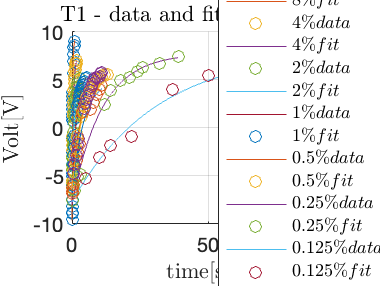

plot(tmg,fung)
hold on
scatter(timeT1g,VoltT1g)
hold on


legend("Position",[0.71243,0.15617,0.19276,0.54961])
legend('8\% data','$8\% fit$','$4\% data$',...
    '$4\% fit$','$2\% data$','$2\% fit$',...
    '$1\% data$','$1\% fit$','$0.5\% data$',...
    '$0.5\% fit$','$0.25\% data$','$0.25\% fit$',...
    '$0.125\% data$','$0.125\% fit$',...
    'unknown data','unknown fit','gly data',...
    'gly fit','interpreter','latex')
% xlim([-0.04 4.50])
% ylim([-10.1 9.9])
legend("Position",[0.74196,0.1536,0.17589,0.50119])
title('T1 - data and fit Volt vs. time',Interpreter='latex')
ylabel('Volt[V]',Interpreter='latex')
xlabel('time[sec]',Interpreter='latex')
grid on

% savefig(f,'T1_fit.png')